# Practical: Sequence alignment

In this practical you will implement the algorithm for global sequence alignment in Matlab. We limit ourselves to sequences of DNA nucleotides: A, C, T, G. 

### Assignment 8 - Basic Needleman-Wunsch algorithm (35)

- Implement the basic Needleman-Wunsch algorithm from the reader in Matlab. Give the file with your program the name nw1.m (or insert it in the code block below). Your program should read two sequences of length n and m from an input file. This can be done by the following lines of Matlab code (assuming the input file is input.txt):

in = fopen('input.txt'); % open input file
s = fgetl(in); % readline 1 of the input
t = fgetl(in); % readline 2 of the input
fclose(in); % close file
lens = length(s); % length string s
lent = length(t); % length string t

% Here comes your code

% The result should be a matrix $D$ containing the costs of optimal alignment

The scoring matrix w(ai , bj) has the form:

That is, the costs of a match are p and of a mismatch q, e.g., *w(A, A) = p, w(A, T) = q*, etc. Furthermore, the gap penalty is *g*. The parameters *p, q* and *g *should be variables in your algorithm, to be initialized at the start of your Matlab-program. The result of your program is a *(n + 1) × (m + 1)-* dimensional matrix *D* containing the costs of optimal alignment.

- Inspect the file *nw_test1.txt* from the archive *Practical_SequenceAlignment *in Nestor. This file contains the two sequences: 

Run your program nw1.m in Matlab with nw_test1.txt as input, and the following values of the parameters: *p = 0, q = 4, g = 5*. The matrix *D* that contains the costs (edit distances) of the alignment should agree with the matrix at the bottom of p. 26 of the syllabus (without the arrows). 

### Assignment 9 - Needleman-Wunsch algorithm with predecessors (35)

Next you will expand the basic algorithm so that not only the costs of an optimal alignment are computed, but also the predecessors. We limit ourselves to the determination of *one* predecessor for each position *(i, j)*.

- Implement the Needleman-Wunsch algorithm with predecessors in Matlab by expanding your program nw1.m. Call your new program nw2.m (or copy it and alter it below). The input and parameters are the same as in Assignment 8. The result of your program should be as follows:

                a) a *(n + 1) × (m + 1)*-dimensional matrix *D* with the the optimal alignment (as in Assignment 8);

                b) *a (n + 1) × (m + 1)-*dimensional matrix *P*, whose elements indicate the direction of the predecessor. For this purpose we use simple characters that occur on your keyboard, that is, ’|’ for “from the north”, ’-’ for “from the west”, and ’\’ for “from the north west”. More precisely:

N.B. The last case occurs at the position on the first row and the first column. In case there is more than one predecessor, you have to choose one, with the following priority order: north west; west; north. 

% Insert Code Here

- Run your program nw2.m, again with nw_test1.txt as input, and the same values of the parameters: *p = 0, q = 4, g = 5*. Let Matlab print the matrices D and P below one another on stdout. The result should be as follows (see also the reader): 

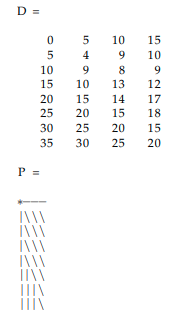

### Assignment 10 - Needleman-Wunsch algorithm with optimal alignment (30)

Finally, you will expand the algorithm such that also the optimal alignment is determined. Use your program nw2.m as basis. Call the corresponding program nw3.m (or insert it in the code block below). 

- Compute the alignment of the two input strings s and t. By determining the trace-back path (repeatedly following the predecessor) you can walk back from the endpoint *(n + 1, m + 1)* to the starting point (1, 1). (Because we have chosen only a single predecessor in each point there is also only *one* optimal alignment.) The strings after alignment we call *s_al* and *t_al*. So these are calculated “from back to front”. Determine during the calculation also a string *l_al* (with the same length as s_al and t_al) which has a ’|’ symbol on position *k* if a match occurs between the input strings at that position, and a space otherwise.

% Insert Code Here

- Run your program nw3.m, again with nw_test1.txt as input, and the same values of the parameters: *p = 0, q = 4, g = 5*. Let Matlab print the strings *s_al*, *l_al* and* t_al *orderly formatted below one another on stdout. The result should be as follows:

- Instead of printing the results on stdout by the printf function you can also print the results to a file by the fprintf function, as follows. Include the following lines at the end of your program nw3.m, and add the missing code for printing (These can also be found in the file print to file.m from the archive Practical SequenceAlignment). The code for printing the input sequences has already been inserted.

output = fopen('nw3-output.txt', 'w'); % open file
fprintf(output, 'Name: <Your name(s)>\n'); % enter your name(s)
fprintf(output, 'IBC, Practical 3\n\n');

fprintf(output, '\n\nString s: \n');
for i=1:length(s)
    fprintf(output, '%s', s(i));
end
fprintf(output, '\n\nString t: \n');
for i=1:length(t)
    fprintf(output, '%s', t(i));
end

fprintf(output, '\n\nMatrix D: \n\n');
% Here comes the code for printing matrix D

fprintf(output, '\n\nMatrix P: \n\n');
% Here comes the code for printing matrix P

fprintf(output, '\n\nAlignment: \n\n');
% Here comes the code for printing the alignment
% That is, strings s_al , l_al , t_al below one another (aligned)

fclose(output); % close file

Run your program nw3.m again and check that the file nw3-output.txt contains the correct information.

**Hand in:**

- a concise report in PDF format (generated by LaTeX), in which: 

a. you describe, for each part of every assignment, how you arrived at the solution, 

b. you answer all the questions posed in the assignments. 

Write at the top of the first page of your report: “Introduction to Scientific Computing, Practical Sequence Alignment”, followed by your name(s), student number(s), and the date when you hand in the report.

- your Matlab programs nw1.m,... , nw3.m. 

Since you work in pairs, you need to include information in your report about your individual contributions. For each assignment, indicate the contribution (mention percentages) for each of you in terms of tasks performed (program design, program implementation, answering questions posed, writing the report). All files have to be handed in as **a single archive **(called YourName.zip), where “YourName” is the concatenation of your last names (or your last name, if you work individually). See Nestor for the address to which you have to send the archive.